## EEGLAB Preprocessing

participant = "P13_2024_08_30_Hum_300Hz_A_Cont.mat";

tic
eeglab

Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\darre\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "EEG-BIDS" v10.3 (see >> help eegplugin_eegbids) - new version 10.5 available
EEGLAB: adding "ICLabel" v1.7 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.11 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "cleanline" v2.1 (see >> help eegplugin_cleanline)
EEGLAB: adding "dipfit" v5.6 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)


EEG.etc.eeglabvers = '2025.1.0'; % this tracks which version of EEGLAB is being used, you may ignore it
EEG = pop_importdata('dataformat','matlab','nbchan',0,'data',sprintf('C:\\Users\\darre\\Projects\\MATLAB\\ICA_MEP_classifier\\%s', participant),'srate',4000,'pnts',0,'xmin',0);

pop_editset(): raw data file 'C:\Users\darre\Projects\MATLAB\ICA_MEP_classifier\P13_2024_08_30_Hum_300Hz_A_Cont.mat' found
eeg_checkset warning: number of rows in data (69) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (2179753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


EEG.setname=participant;
EEG = pop_chanevent(EEG, 69,'edge','leading','edgelen',1,'duration','on','nbtype',1);

pop_chanevent: importing events from data channel 69 ...
eeg_checkset note: creating the original event table (EEG.urevent)
Removing 1 channel(s)...


%Events are now saved in EEG.event


fs = EEG.srate;
data_blanked = EEG;
stimStart = 0.01*fs;
blankEnd = 0.01*fs;
pulseTimes = [EEG.event.latency]; 
t = [0:size(data_blanked.data, 2)-1]/fs;

%blanking
%likely chance index 1 is a false trigger
for f = 2:length(pulseTimes)
    data_blanked.data(:, pulseTimes(f) -stimStart:pulseTimes(f) +blankEnd) = NaN;
end

% interpolation
for h = 1:size(data_blanked.data, 1)
    inn = isnan(data_blanked.data(h,:));
    data_blanked.data(h, inn) = interp1(t(~inn), data_blanked.data(h, ~inn), t(inn));
end

assert(~any(isnan(data_blanked.data(:))), 'Data contains NaNs!');

EEG.data = data_blanked.data;

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


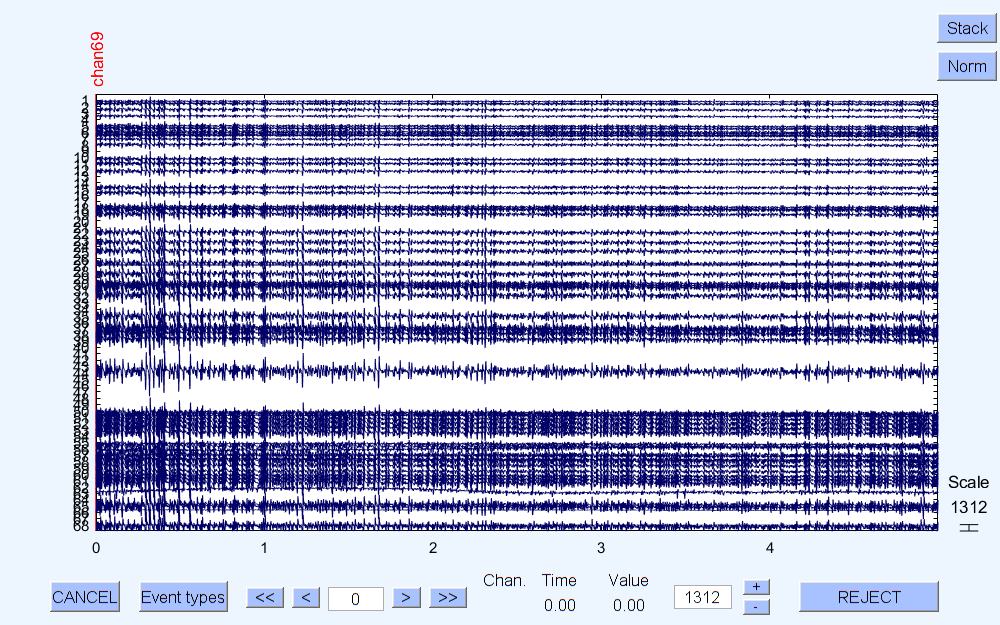

pop_eegplot( EEG, 1, 1, 1);

EEG = pop_resample( EEG, 1000);

resampling data 1000.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 
resampling event latencies...
resampling finished


pop_eegfiltnew() - performing 529 point bandpass filtering.
pop_eegfiltnew() - transition band width: 6.25 Hz
pop_eegfiltnew() - passband edge(s): [25 400] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [21.875 403.125] Hz


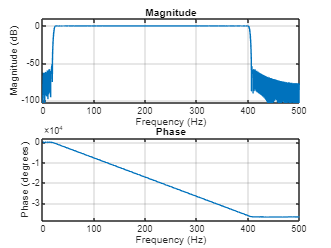

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


%EEG = pop_rmdat( EEG, {'chan69'},[-0.01 0.01] ,1);

EEG = pop_eegfiltnew(EEG, 'locutoff',25,'hicutoff',400,'plotfreqz',1);

% EEG = pop_firws(EEG, 'fcutoff', [25 400], 'ftype', 'bandpass', 'wtype', 'kaiser', 'warg', 5.65326, 'forder', 7246, 'minphase', 0, 'usefftfilt', 1, 'plotfresp', 0, 'causal', 0);
EEG.setname=sprintf('%s resampled filtered 1', participant);

EEG = pop_cleanline(EEG, 'bandwidth',2,'chanlist',[1:68] ,'computepower',1,'linefreqs',60,'newversion',0,'normSpectrum',0,'p',0.01,'pad',2,'plotfigures',0,'scanforlines',1,'sigtype','Channels','taperbandwidth',2,'tau',100,'verb',1,'winsize',4,'winstep',2);



Welcome to the CleanLine line noise removal toolbox!
CleanLine is written by Tim Mullen (tim@sccn.ucsd.edu) and uses multi-taper routines modified from the Chronux toolbox (www.chronux.org)

Tsk Tsk, you've allowed your data to get very dirty!
Let's roll up our sleeves and do some cleaning!
Today we're going to be cleaning your Channels

[!] Please note that because the selected window length does not divide the data length, 
    0.939 seconds of data at the end of the record will not be cleaned.

Multi-taper parameters follow:
	Time-bandwidth product:	 4
	Number of tapers:	 7
	Number of FFT points:	 16384
I'm going try to remove lines at these frequencies: [60] Hz
I'm going to scan the range +/-1 Hz around each of the above frequencies for the exact line frequency.
I'll do this by selecting the frequency that maximizes Thompson's F-statistic above a threshold of p=0.01.

OK, now stand back and let The Maid sho

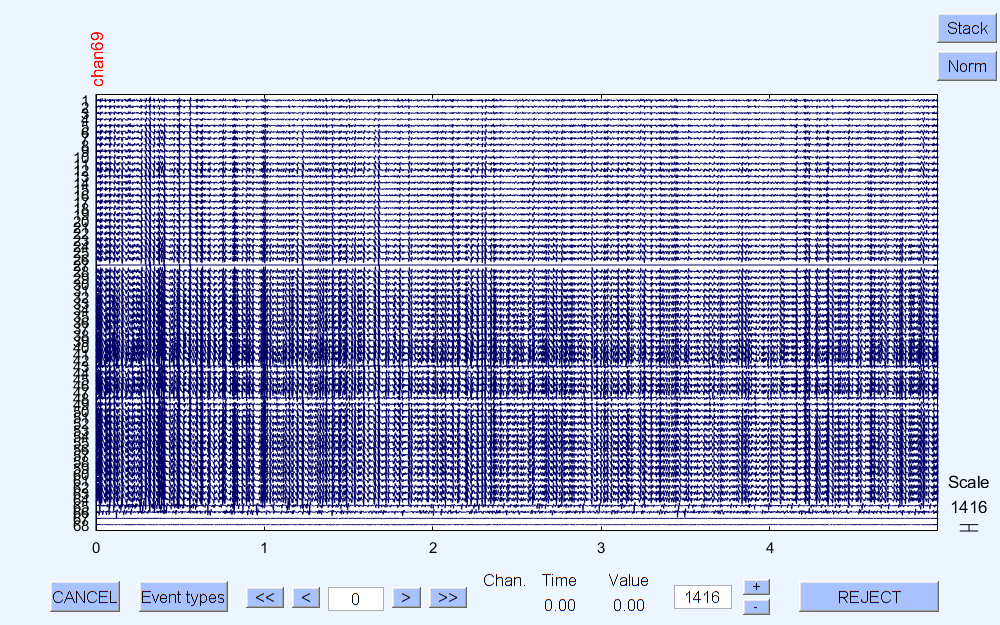

%EEG = pop_firws(EEG, 'fcutoff', [59 61], 'ftype', 'bandstop', 'wtype', 'kaiser', 'warg', 5.65326, 'forder', 7246, 'minphase', 0, 'usefftfilt', 1, 'plotfresp', 0, 'causal', 0);
EEG.setname=sprintf('%s resampled filtered 2', participant);

pop_eegplot( EEG, 1, 1, 1);

EEG = pop_epoch( EEG, {  'chan69'  }, [-0.1       0.1], 'newname', sprintf('%s resampled filtered 2 epochs', participant), 'epochinfo', 'yes');

pop_epoch():420 epochs selected
Epoching...
pop_epoch():419 epochs generated
pop_epoch(): checking epochs for data discontinuity


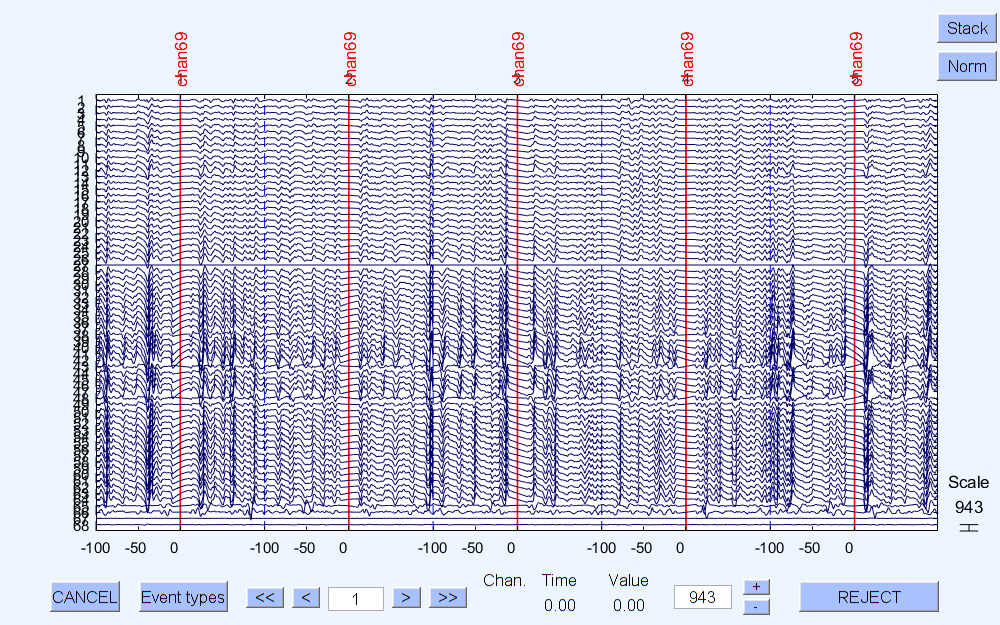

pop_eegplot( EEG, 1, 1, 1);

EEG=pop_chanedit(EEG, 'load',[],'load',{'C:\\Users\\darre\\Projects\\MATLAB\\ICA_MEP_classifier\\hdemg_patch.xyz','filetype','xyz'});

readlocs(): Re-sorting channel numbers based on 'channum' column indices


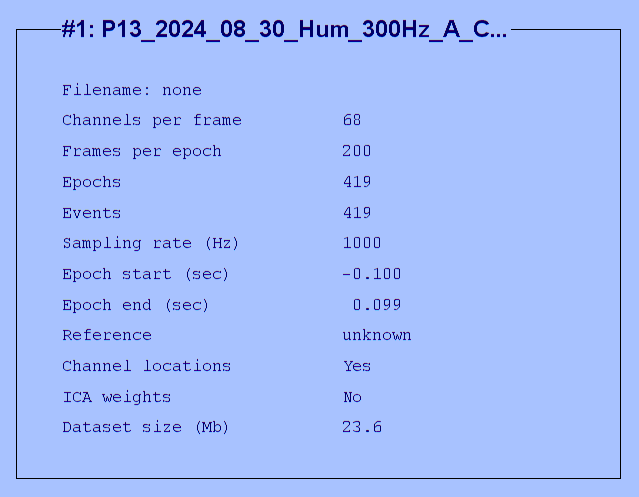

%EEG = pop_select( EEG, 'rmchannel',{'UNI1','UNI6','UNI7','UNI8'});
eeglab redraw

toc

Elapsed time is 24.417974 seconds.



% now do ICA